## Analysis of Communication vs Computation Time

Using the large strong scaling dataset, I took the time each processor took to perform calculations and communicate back to rank 0. After averaging those times, the following plots were generated.

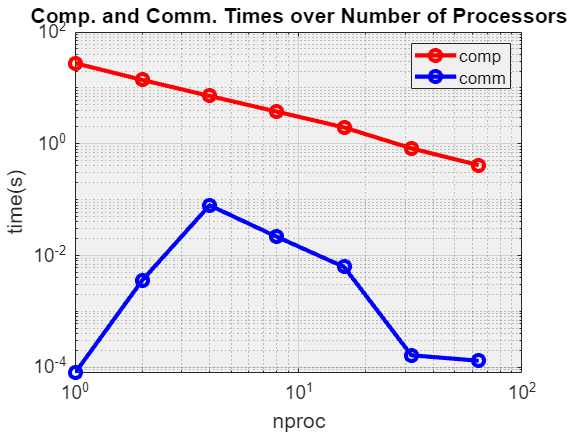

%Reading data


%Plot
loglog(nproc,comp,'ro-',nproc,comm,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('time(s)','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240]);
title('Comp. and Comm. Times over Number of Processors');
legend('comp','comm','Location','northeast');

For the first three trials, the communication and computation times show an expected direction. However, to my surprise, from 16 processors and on, the communication time decreases as computation time decreases as well. Regardless, the communication time is extremely low and negligible for the most part, as the only MPICH library function used to communicate is Reduce. Because of this, communication times can stay low while computation times steadily decrease as number of processors increases. This can help explain the over 100% efficiency demonstrated in the strong scaling efficiency. Normally, when computation and communication cross, that is when the program is reaching it's computational limits. Based on what this plot is telling us, this algorithm could complete a massive amount of computations with very little time wasted on communication.

Plotting the speedup and efficiency of both the computation and communication times alone might tell more about what is happening. Here is the speedup and efficiency of the computational execution time of the large strong scaling experiment.

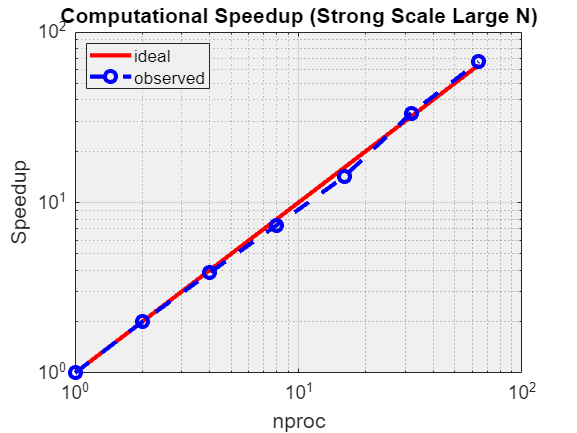

%Reading data
speedData=readmatrix('timeData.csv');
nproc=speedData(:,1);
time=speedData(:,2);

speedup = time(1)./time;
idealSpeedup = nproc;
%Speedup
loglog(nproc,idealSpeedup,'r-',nproc,speedup,'bo--','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Speedup','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Computational Speedup (Strong Scale Large N)');
legend('ideal','observed','Location','northwest');

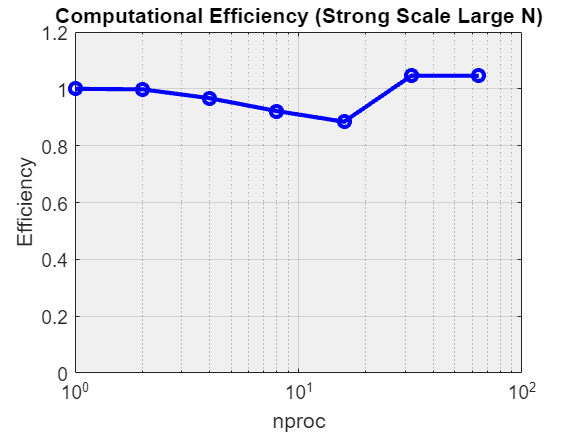


%Efficiency (Strong)
E = speedup./nproc;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1.2]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240]);
title('Computational Efficiency (Strong Scale Large N)');

As mentioned previously, the communication times in this experiment proved to be so small that they were practically negligible. This is why in this situation we see a direct correlation between the speedup and efficiency plots of the large strong scaling experiment and its computational time. Mathematically, if computation takes up most of the time, it will have the most effect on the plots themselves. Now it's time to look at the communication plots.

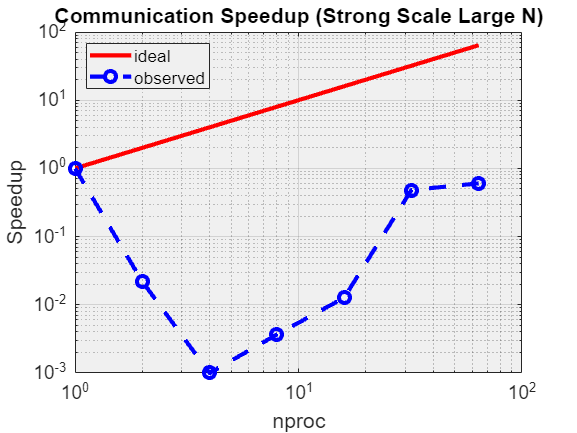

%Reading data
speedData=readmatrix('timeData.csv');
nproc=speedData(:,1);
time=speedData(:,3);

speedup = time(1)./time;
idealSpeedup = nproc;
%Speedup
loglog(nproc,idealSpeedup,'r-',nproc,speedup,'bo--','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Speedup','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Communication Speedup (Strong Scale Large N)');
legend('ideal','observed','Location','northwest');

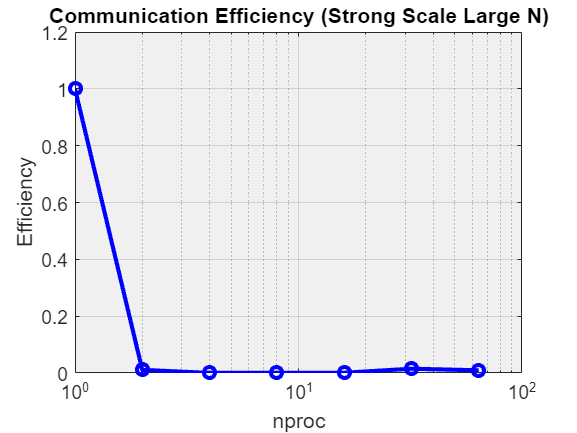


%Efficiency (Strong)
E = speedup./nproc;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1.2]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240]);
title('Communication Efficiency (Strong Scale Large N)');

As expected, communication has a terrible speedup and efficiency. This part of the Monte Carlo method does not contribute to finding the solution, and thus is going to be extremely inefficient. Fortunately in this case, there is not much required communication to solve the problem as each processor is able to generate its own data. In cases where more communication is present, this can cause major issues in the overall speedup and certainly weigh down the overall speedup when strong scaling an algorithm.

In conclusion, there must be a balance in parallel computing. The computational power of the machine, the size of the problem, and the amount of communication needed are all important factors when deciding the most optimal way to parallelize a program.